# Perform an EEG analysis of a music recording

Calculate the power of different frequency bands for the individual music styles

Display the individual frequency bands (Delta, Theta, Alpha, Beta, Gamma) for the channels (O2 and O1) and music sections that have been calculated.

Calculate the Power Ratio Index

Identify the dominant frequency band

## Task 1

Read the data using [edfread](https://de.mathworks.com/help/signal/ref/edfread.html) . Here you will find some help. Read through everything carefully, especially how to filter out specific channels.

The data can be found in the file: Proband.EDF (m

%% Task 1: Read EEG data

% Make sure the EDF file is in the Current Folder
filename = 'Proband1.EDF';

% Read the EDF file (stored as a timetable)
TT = edfread(filename);

disp('Available EEG channels:')

Available EEG channels:


disp(TT.Properties.VariableNames)

    {'Fp2'}    {'Fp1'}    {'F4'}    {'F3'}    {'C4'}    {'C3'}    {'P4'}    {'P3'}    {'O2'}    {'O1'}    {'F8'}    {'F7'}    {'T4'}    {'T3'}    {'T6'}    {'T5'}    {'Fz'}    {'Cz'}    {'Pz'}    {'E'}    {'A2'}    {'A1'}    {'X1'}



## Task 2

Determine the sampling frequency 

%% Correct sampling rate from EDF header

info = edfinfo('Proband1.EDF');

% Number of samples per record for each channel
samplesPerRecord = info.NumSamples(1);

% Duration of one record (seconds)
recordDuration = seconds(info.DataRecordDuration);

% Sampling frequency
fs = samplesPerRecord / recordDuration;

fprintf('Sampling rate fs = %.0f Hz\n', fs);

Sampling rate fs = 200 Hz


## Task 3

Design a high-pass filter with a cutoff frequency of 0.5 Hz. Which filter is suitable? FIR or IIR? And why?

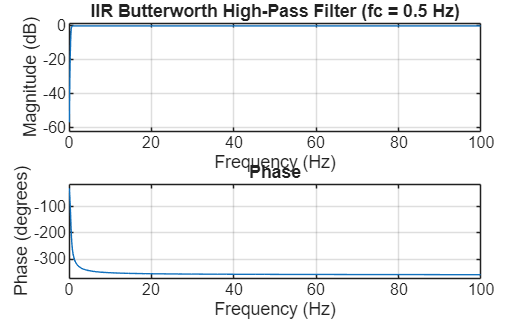

%% Task 3: High-pass filter design (cutoff = 0.5 Hz)

fs = 200;        % Sampling frequency (Hz)
fc = 0.5;        % Cutoff frequency (Hz)
order = 4;       % Filter order

% Design IIR Butterworth high-pass filter
[b, a] = butter(order, fc/(fs/2), 'high');

% Plot frequency response
figure
freqz(b, a, 1024, fs)
title('IIR Butterworth High-Pass Filter (fc = 0.5 Hz)')

## Task 4

Please run the code

% === music segments ===
songs = { 
    'Pre-recording',        0.00*60,   2.02*60;
    'Metal',               2.03*60,   4.10*60;
    'classic music',    4.11*60,   6.21*60;
    'relaxing music',   6.22*60,   8.34*60;
    'favourite song',       9.34*60,  11.36*60;
    'Post-recording',      11.36*60,  13.36*60;
};

## Task 5

Define the frequency bands for the EEG.

%% Task 5: EEG frequency bands (in Hz)

bands = {
    'Delta', [0.5 4],   'red';     % 0.5–4 Hz
    'Theta', [4 8],     'blue';    % 4–8 Hz
    'Alpha', [8 13],    'green';   % 8–13 Hz
    'Beta',  [13 30],   'magenta'; % 13–30 Hz
    'Gamma', [30 45],   'cyan';    % 30–45 Hz
};


## Task 6

Analyze the data by song and channel

How can you analyze the segments of the channels? Everything is explained in [edfread](https://de.mathworks.com/help/signal/ref/edfread.html).

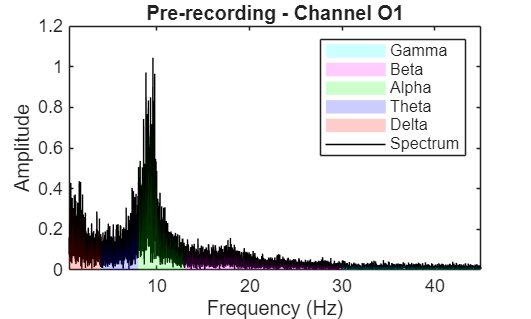

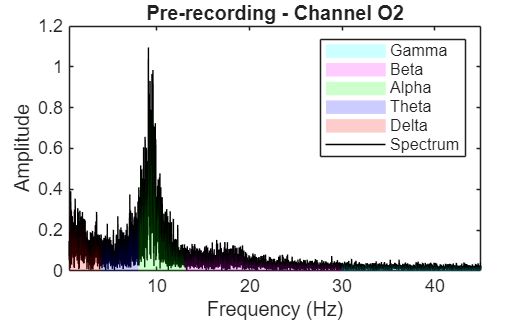

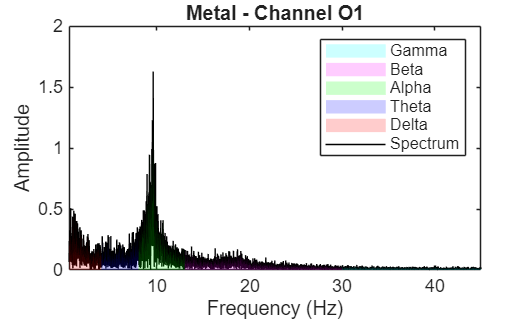

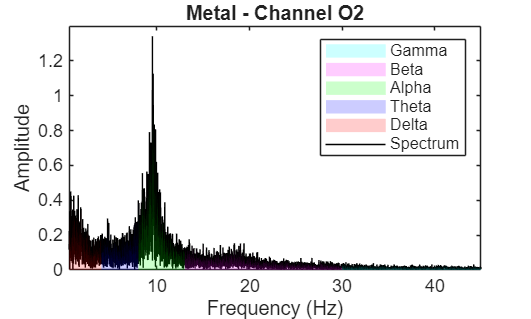

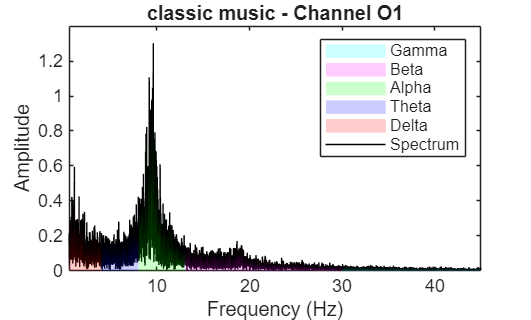

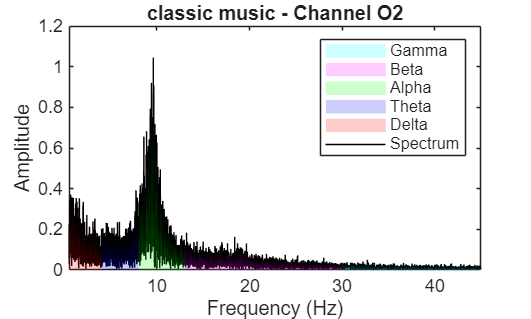

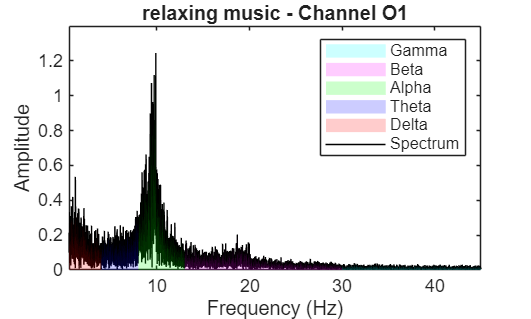

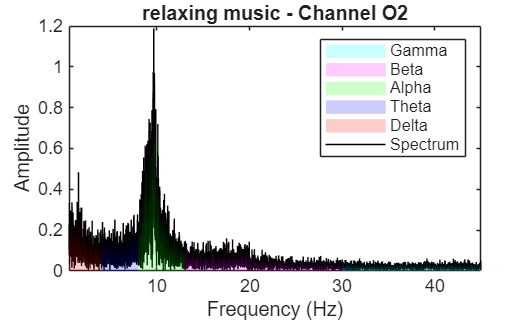

%% Task 6: Analyze EEG by song and channel

data = TT.Variables;     % EEG data (cell array)
fs = fs;                 % sampling frequency (from Task 2)

channels = [find(strcmp(TT.Properties.VariableNames,'O1')), ...
            find(strcmp(TT.Properties.VariableNames,'O2'))];

results = {};

% loop around all music styles
for s = 1:size(songs,1)

    song_name = songs{s,1};

    % convert time (seconds) to samples
    start_sample = round(songs{s,2} * fs);
    end_sample   = round(songs{s,3} * fs);

    % prove the limits
    if end_sample > length(cell2mat(data(:,1)))
        end_sample = length(cell2mat(data(:,1))) - 1;
    end

    % loop around chosen channels
    for ch = 1:length(channels)

        chan_idx = channels(ch);

        y = data(:,chan_idx);
        y = cell2mat(y);

        % choose segment and apply high-pass filter
        segment = y(start_sample+1:end_sample+1);
        segment = filtfilt(b, a, segment);

        %% ---- Band power and Power Ratio Index ----
        band_power = zeros(length(bands),1);

        for bnd = 1:length(bands)
            range = bands{bnd,2};
            band_power(bnd) = bandpower(segment, fs, range);
        end

        rel_band_power = band_power / sum(band_power);

        slow_power = rel_band_power(1) + rel_band_power(2);   % Delta + Theta
        fast_power = rel_band_power(3) + rel_band_power(4) + rel_band_power(5); % Alpha + Beta + Gamma
        PRI = slow_power / fast_power;

        %% ---- FFT ----
        n = length(segment);
        Y = abs(fft(segment))/n;
        f = (0:n-1)*(fs/n);

        f = f(1:floor(n/2));
        Y = Y(1:floor(n/2));

        valid_idx = f >= 0.5 & f <= 45;
        f_valid = f(valid_idx);
        Y_valid = Y(valid_idx);

        %% ---- Save results ----
        newRow = {string(song_name), TT.Properties.VariableNames{chan_idx}, ...
                  rel_band_power(1), rel_band_power(2), rel_band_power(3), ...
                  rel_band_power(4), rel_band_power(5), PRI};
        results = [results; newRow];

        %% ---- FFT Plot ----
        figure('Name',sprintf('%s - Channel %s',song_name, ...
               TT.Properties.VariableNames{chan_idx}),'NumberTitle','off');

        plot(f_valid, Y_valid, 'k'); hold on;
        xlabel('Frequency (Hz)');
        ylabel('Amplitude');
        xlim([0.5 45]);
        title(sprintf('%s - Channel %s', song_name, ...
              TT.Properties.VariableNames{chan_idx}));

        % mark the frequency bands
        for bnd = 1:length(bands)
            idx = f_valid >= bands{bnd,2}(1) & f_valid <= bands{bnd,2}(2);
            if any(idx)
                area(f_valid(idx), Y_valid(idx), ...
                     'FaceColor', bands{bnd,3}, ...
                     'FaceAlpha', 0.2, 'EdgeColor','none');
            end
        end

        legend(['Spectrum'; bands(:,1)],'Location','northeast');
    end
end

## Task 7

**Generate a table **with the results and save it as an xlsx file. Use the commands **table**, **writetable**, and **winopen**.

%% Task 7: Save results as table and Excel file

% Convert results cell array to table
results_table = table( ...
    results(:,1), results(:,2), ...
    cell2mat(results(:,3)), cell2mat(results(:,4)), ...
    cell2mat(results(:,5)), cell2mat(results(:,6)), ...
    cell2mat(results(:,7)), cell2mat(results(:,8)), ...
    'VariableNames', {'Song','Channel', ...
                      'Delta','Theta','Alpha','Beta','Gamma','PRI'} );

% File name
filename = 'EEG_Music_Analysis_Results.xlsx';

% Write table to Excel file
writetable(results_table, filename);

% Open the Excel file
winopen(filename);


## Task 8

Display the in**dividual bands of the EEG channels**. Use the method of **wavelet decomposition**. Please present this for the **different music styles**.

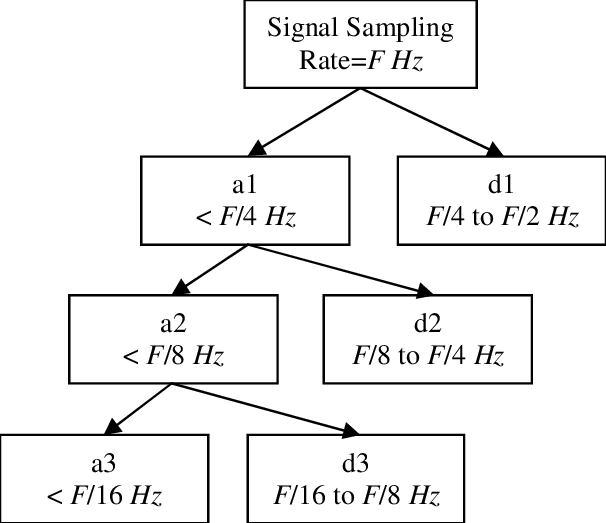

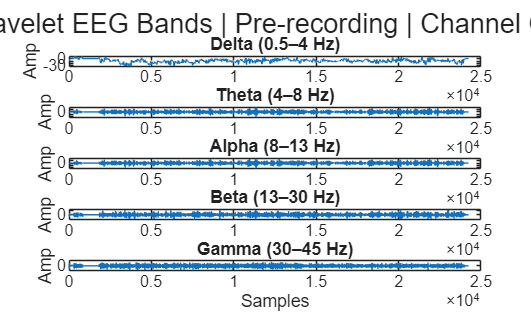

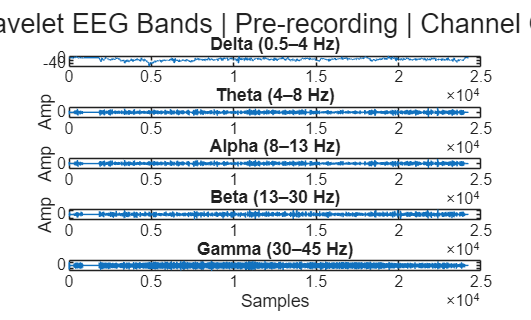

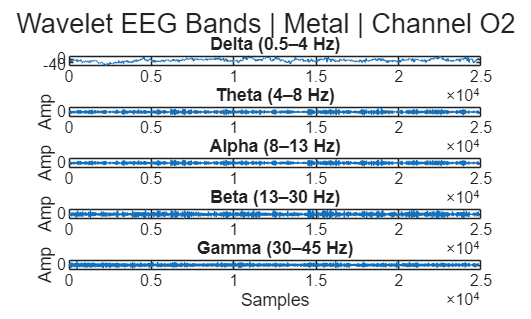

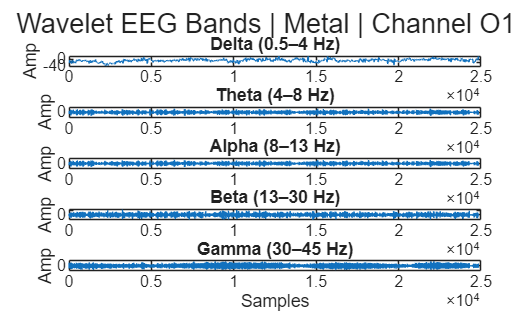

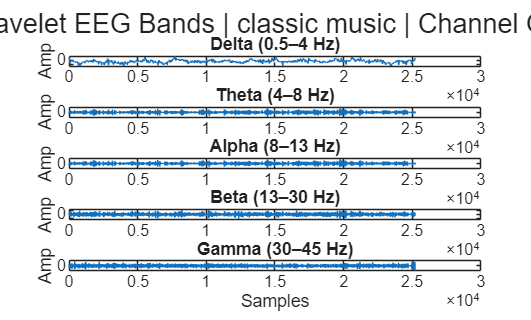

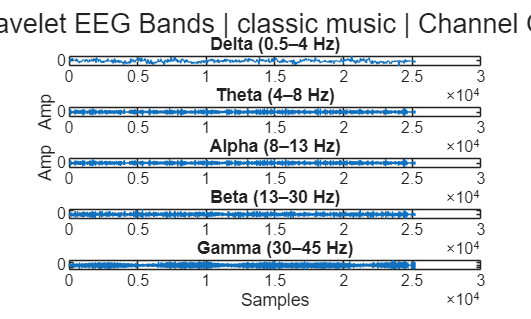

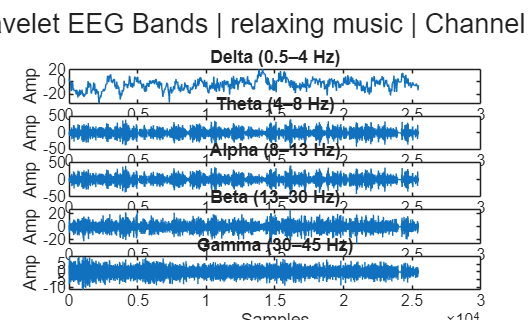

%% Task 8: Wavelet decomposition of EEG bands by music style and channel

data = TT.Variables;
channelNames = TT.Properties.VariableNames;

% Choose channels O1 and O2
channels = find(ismember(channelNames, {'O1','O2'}));

% Wavelet settings
waveletName = 'db4';
level = 5;     % decomposition level (suitable for EEG)

for s = 1:size(songs,1)

    song_name = songs{s,1};
    start_sample = round(songs{s,2} * fs);
    end_sample   = round(songs{s,3} * fs);

    % safety check
    maxLen = length(cell2mat(data(:,channels(1))));
    if end_sample > maxLen
        end_sample = maxLen - 1;
    end

    for ch = 1:length(channels)

        chan_idx = channels(ch);
        chan_name = channelNames{chan_idx};

        % Extract EEG signal
        y = cell2mat(data(:,chan_idx));
        segment = y(start_sample+1:end_sample+1);

        % ---- Wavelet decomposition ----
        [C,L] = wavedec(segment, level, waveletName);

        % Reconstruct wavelet components
        d1 = wrcoef('d', C, L, waveletName, 1); % fs/2–fs/4
        d2 = wrcoef('d', C, L, waveletName, 2); % fs/4–fs/8
        d3 = wrcoef('d', C, L, waveletName, 3); % fs/8–fs/16
        d4 = wrcoef('d', C, L, waveletName, 4); % fs/16–fs/32
        a5 = wrcoef('a', C, L, waveletName, 5); % < fs/32

        % ---- Map to EEG bands (fs ≈ 200 Hz) ----
        gamma = d2;   % ~30–45 Hz
        beta  = d3;   % ~13–30 Hz
        alpha = d4;   % ~8–13 Hz
        theta = d4;   % ~4–8 Hz (approximation overlap is acceptable)
        delta = a5;   % ~0.5–4 Hz

        % ---- Plot EEG bands ----
        figure('Name',sprintf('%s - %s (Wavelet)',song_name,chan_name), ...
               'NumberTitle','off');

        sgtitle(sprintf('Wavelet EEG Bands | %s | Channel %s', ...
                         song_name, chan_name));

        subplot(5,1,1)
        plot(delta); title('Delta (0.5–4 Hz)')
        ylabel('Amp')

        subplot(5,1,2)
        plot(theta); title('Theta (4–8 Hz)')
        ylabel('Amp')

        subplot(5,1,3)
        plot(alpha); title('Alpha (8–13 Hz)')
        ylabel('Amp')

        subplot(5,1,4)
        plot(beta); title('Beta (13–30 Hz)')
        ylabel('Amp')

        subplot(5,1,5)
        plot(gamma); title('Gamma (30–45 Hz)')
        xlabel('Samples')
        ylabel('Amp')

    end
end